clc ;
clear all ;
close all;
%low pass filter
% Load input ECG signal data
load("rec_2m.mat");
x = val(1,1:1500);
L=length(x)

L = 1500

Sampling_frequency=500

Sampling_frequency = 500

t=(1:L)*(1/Sampling_frequency);
Fs=Sampling_frequency

Fs = 500

Transition_band=1

Transition_band = 1

Fp=49

Fp = 49

Sampling_time=1/Sampling_frequency

Sampling_time = 0.0020

Omega_p=2*pi*Fp

Omega_p = 307.8761

Omega_s=2*pi*(Fp+Transition_band)

Omega_s = 314.1593

%%Converting the analog filter specifications into digital specification
%%using the formula, w=Omega*Sampling_Time
Wp=Omega_p*Sampling_time

Wp = 0.6158

Ws=Omega_s*Sampling_time

Ws = 0.6283


%% The filter should provide minimum 50 dB attenuation in the stop band
%% Select the appropriate window to meet the requirement
% Order of the filter
k=6 % k value for hamming, hanning and bartlet window

k = 6

N=(12*pi)/(Ws-Wp)

N = 3.0000e+03

N=ceil(N)% To get the alpha as an integer

N = 3001

%convert N to nearest odd number
if(rem(N,2)==0)
    N=N+1
end
Alpha=(N-1)/2

Alpha = 1500



%%Cutoff frequency
%%
Wc=Wp+((Ws-Wp)/2)

Wc = 0.6220


%% Hamming Window function
n = 0:N-1;
WBlack = 0.42 - 0.5* cos(2 * pi * n / (N - 1)) + 0.08* cos(4 * pi * n / (N - 1)); 

%%The impulse response of the desired lowpass filter 
%%S
h = zeros(1, N);
for i = 1:N
    if i-1 == Alpha 
        h(i) = Wc / pi;
    else
        h(i) = sin(Wc * (i - Alpha - 1)) / (pi * (i - Alpha - 1));
    end
end
h1 = h .* WBlack;
%% Apply the FIR filter to the input ECG signal
filtered_signal = conv(x, h1, 'same');


%% High pass filter design
Transition_band=1

Transition_band = 1

Fp=8

Fp = 8

Sampling_time=1/Sampling_frequency

Sampling_time = 0.0020

Omega_p=2*pi*Fp

Omega_p = 50.2655

Omega_s=2*pi*(Fp-Transition_band)

Omega_s = 43.9823

%%Converting the analog filter specifications into digital specification
%%using the formula, w=Omega*Sampling_Time
Wp=Omega_p*Sampling_time

Wp = 0.1005

Ws=Omega_s*Sampling_time

Ws = 0.0880


%% The filter should provide minimum 50 dB attenuation in the stop band
%% Select the appropriate window to meet the requirement
% Order of the filter
k=6 % k value for hamming, hanning and bartlet window

k = 6

N=(12*pi)/(Wp-Ws)

N = 3.0000e+03

N=ceil(N)% To get the alpha as an integer

N = 3000

%convert N to nearest odd number
if(rem(N,2)==0)
    N=N+1
end

N = 3001

Alpha=(N-1)/2

Alpha = 1500


%%Cutoff frequency
%%
Wc=Ws+((Wp-Ws)/2)

Wc = 0.0942

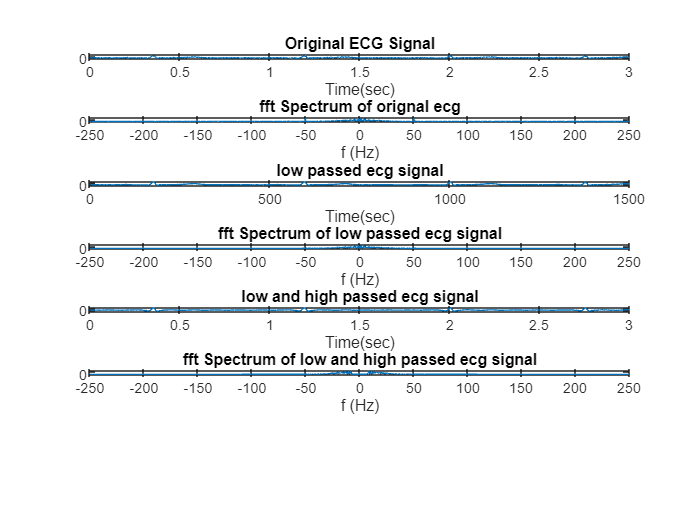


%% Hamming Window function
n = 0:N-1;
WBlack = 0.42 - 0.5* cos(2 * pi * n / (N - 1)) + 0.08* cos(4 * pi * n / (N - 1)); 

%%The impulse response of the desired highpass filter 
%%S
h = zeros(1, N);
for i = 1:N
    if i-1 == Alpha 
    h(i) = (pi - Wc) / pi;
    else
    a = sin(pi * (i - Alpha - 1)) - sin(Wc * (i - Alpha - 1));
    h(i) = a /(pi* (i- Alpha - 1));

    end
end
h2 = h .* WBlack;
%% Apply the FIR filter to the input ECG signal
filtered_signal1 = conv(filtered_signal, h2, 'same');

%alternate method 
h= conv(h1, h2, 'same');
filtered_signal2 = conv(x, h, 'same');



figure;
subplot(7, 1, 1);
plot(t,x);
title('Original ECG Signal');
xlabel('Time(sec)')
ylabel('Amplitude')

subplot(7, 1, 2);
X=fft(x);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X)))
title("fft Spectrum of orignal ecg")
xlabel("f (Hz)")
ylabel("|fft(X)|")

subplot(7, 1, 3);
plot(filtered_signal);
title('low passed ecg signal');
xlabel('Time(sec)')
ylabel('Amplitude')

X1=fft(filtered_signal);
subplot(7, 1, 4);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X1)))
title("fft Spectrum of low passed ecg signal")
xlabel("f (Hz)")
ylabel("|fft(X)|")

subplot(7, 1, 5);
plot(t,filtered_signal1);
title('low and high passed ecg signal');
xlabel('Time(sec)')
ylabel('Amplitude')

X2=fft(filtered_signal1);
subplot(7, 1, 6);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X2)))
title("fft Spectrum of low and high passed ecg signal")
xlabel("f (Hz)")
ylabel("|fft(X)|")




[h,w]=freqz(h,1)

h =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i


w =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


d=(w*Fs)/(2*pi)

d =          0
    0.4883
    0.9766
    1.4648
    1.9531
    2.4414
    2.9297
    3.4180
    3.9062
    4.3945


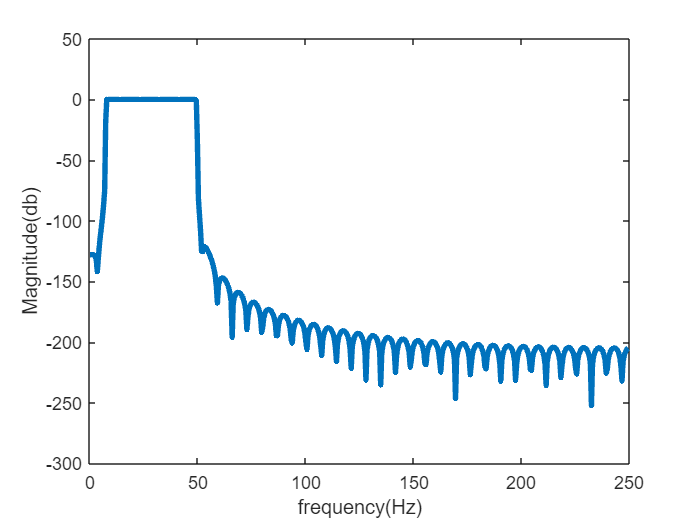

figure;
plot(d,20*log10(abs(h)),linewidth=3)
xlabel('frequency(Hz)')
ylabel('Magnitude(db)')

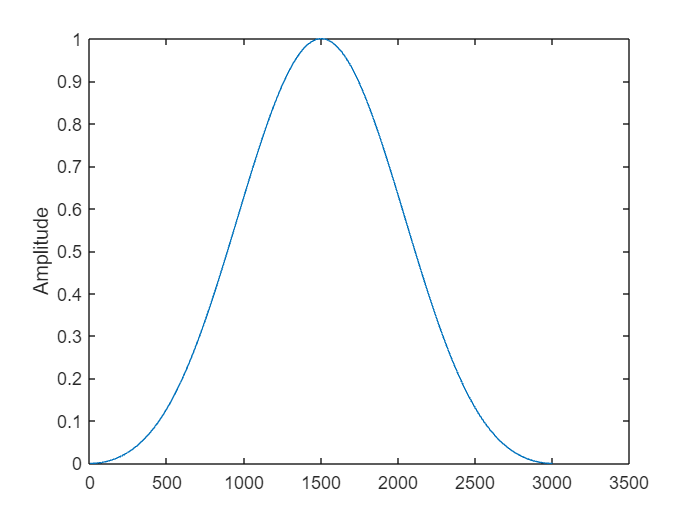


plot(WBlack);
ylabel('Amplitude');

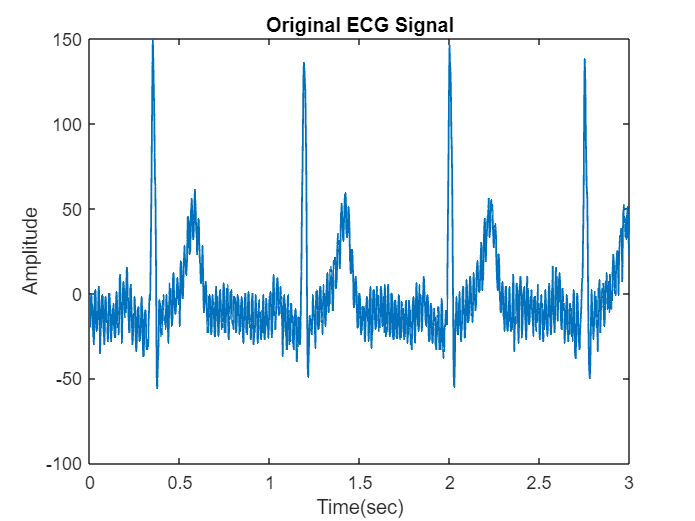


figure;
plot(t,x,linewidth=1);
title('Original ECG Signal');
xlabel('Time(sec)')
ylabel('Amplitude')

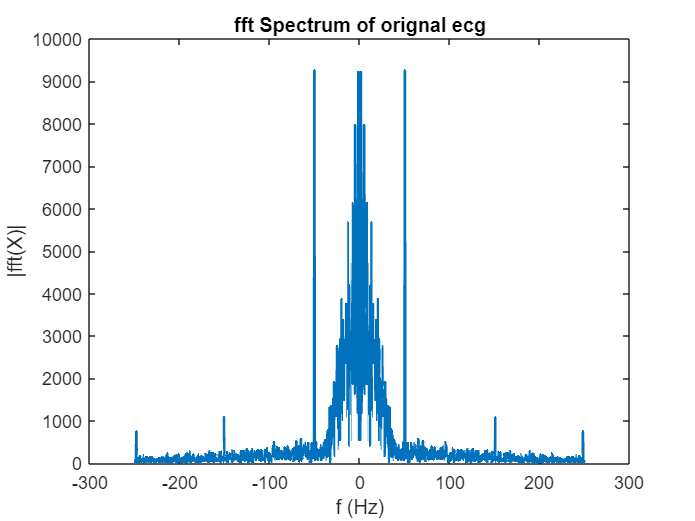


X=fft(x);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X)),linewidth=1.5)
title("fft Spectrum of orignal ecg")
xlabel("f (Hz)")
ylabel("|fft(X)|")

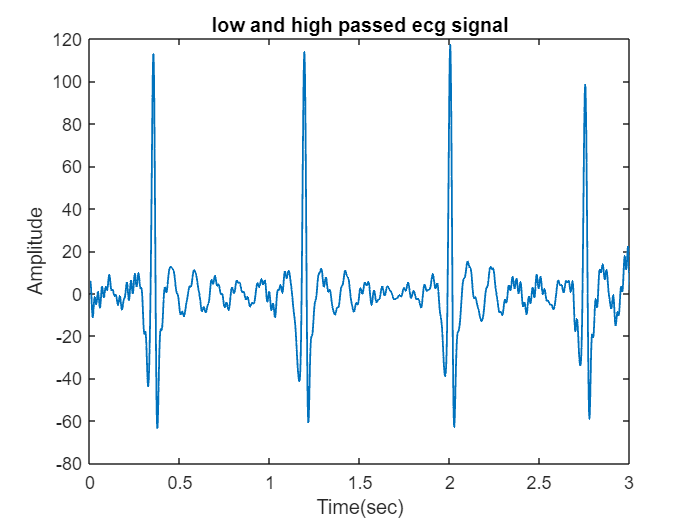


plot(t,filtered_signal1,linewidth=1);
title('low and high passed ecg signal');
xlabel('Time(sec)')
ylabel('Amplitude')

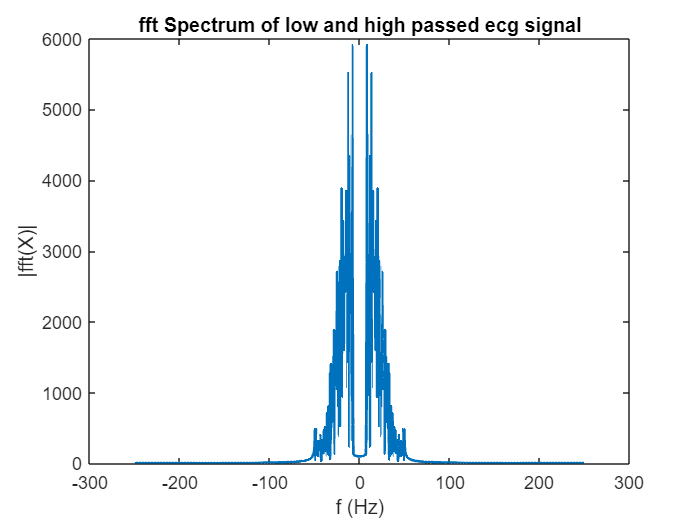


X2=fft(filtered_signal1);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X2)),linewidth=1.5)
title("fft Spectrum of low and high passed ecg signal")
xlabel("f (Hz)")
ylabel("|fft(X)|")